load('flow_data.mat')

# Core Code

## Part A.

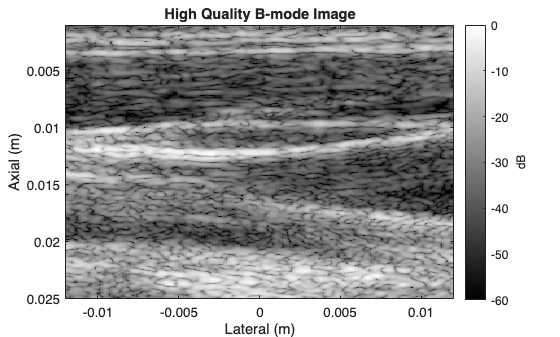

clf;

envh = abs(hilbert(rf_bmode));
envh_db = 20*log10(envh);
norm_envh = envh_db - max(envh_db(:));

figure()
imagesc(x, z, norm_envh);
colormap gray
cb = colorbar;
cb.Label.String = 'dB';
clim([-60 0]);
title('High Quality B-mode Image');
xlabel('Lateral (m)');
ylabel('Axial (m)');

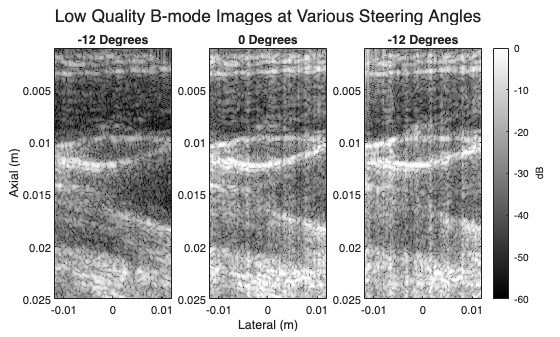


frame = 25;

envl1 = abs(hilbert(rf(:,:,frame,1)));
envl1_db = 20*log10(envl1);
norm_envl1 = envl1_db - max(envl1_db(:));

envl2 = abs(hilbert(rf(:,:,frame,2)));
envl2_db = 20*log10(envl2);
norm_envl2 = envl2_db - max(envl2_db);

envl3 = abs(hilbert(rf(:,:,frame,3)));
envl3_db = 20*log10(envl3);
norm_envl3 = envl3_db - max(envl3_db);

figure()
t = tiledlayout(1, 3);
t.TileSpacing = 'compact';
t.Padding = 'compact';

ax1 = nexttile;
subtitle('-12 Degree')
imagesc(x, z, norm_envl1);
ylabel('Axial (m)');
colormap gray;
clim([-60 0]);
title({'-12 Degrees'});

ax2 = nexttile;
imagesc(x, z, norm_envl2);
xlabel('Lateral (m)');
colormap gray;
clim([-60 0]);
title({'0 Degrees'});

ax3 = nexttile;
imagesc(x, z, norm_envl3);
colormap gray;
cb = colorbar;
cb.Label.String = 'dB';
clim([-60 0]);
title({'-12 Degrees'});
title(t, 'Low Quality B-mode Images at Various Steering Angles');

## Part B. 

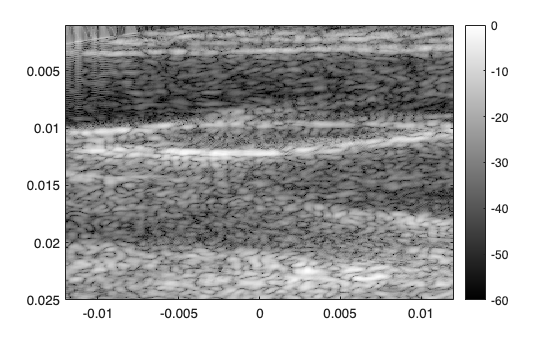

clf;
rf_12 = rf(:,:,:,3);

frames = 50;
M = struct('cdata', {}, 'colormap', {});
M(frames).cdata = [];

vidfile = VideoWriter('b-mode.mp4','MPEG-4');
figure;
open(vidfile);
for i = 1:frames
    % Do we want/need to use hilbert transform here
    env = abs(hilbert(rf_12(:,:,i)));
    env_db = 20*log10(env);
    norm_env = env_db - max(env_db(:));
    
    imagesc(x, z, norm_env);
    colorbar;
    colormap gray;
    clim([-60 0]);

    drawnow;

    M(i) = getframe(gcf);
    writeVideo(vidfile, M(i));
end

close(vidfile);

## Part C.

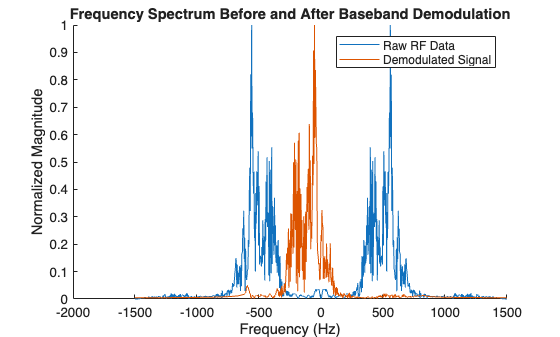

clf;

dt = 2 * (z(2)-z(1)) / c;
t = (0:size(z, 2)-1)' * dt;
quad_demod = hilbert(rf_12);
baseband = quad_demod .* exp(-2 * 1i * pi * f0 * t);


rf_avg = mean(rf_12, [2, 3]);
demod_avg = mean(baseband, [2, 3]);

freq_rf = fftshift(abs(fft(rf_avg)));
freq_rf = freq_rf / max(freq_rf);

freq_demod = fftshift(abs(fft(demod_avg)));
freq_demod = freq_demod / max(freq_demod);

f = (-length(rf_avg) / 2:length(rf_avg)/2 - 1) * (prf / length(rf_avg));

figure;
hold on;
plot(f, freq_rf);
plot(f, freq_demod);
legend(["Raw RF Data", "Demodulated Signal"]);
title("Frequency Spectrum Before and After Baseband Demodulation");
% Add units
xlabel("Frequency (Hz)");
ylabel("Normalized Magnitude");
hold off;

## Part D.

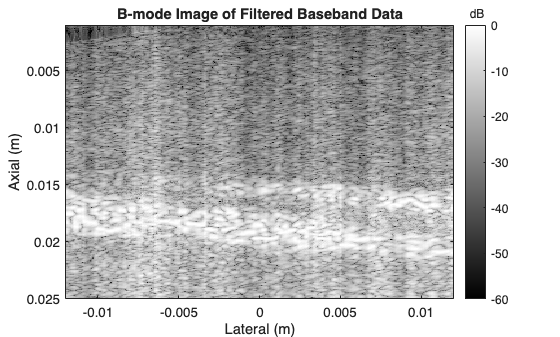


demod_double = double(baseband);
permute_data = permute(demod_double, [3 1 2]);

wf = wall_filter();
[b, a] = tf(wf);

filtered_permutated = filtfilt(b, a, permute_data);
filtered = permute(filtered_permutated, [2 3 1]);

envl_filtered_db = 20*log10(abs(filtered(:, :, frame)));
norm_envl_filtered = envl_filtered_db - max(envl_filtered_db);

imagesc(x, z, norm_envl_filtered);
cb = colorbar;
cb.Title.String = 'dB';
colormap gray;
title('B-mode Image of Filtered Baseband Data');
xlabel('Lateral (m)');
ylabel('Axial (m)');
clim([-60 0]);

## Part E.

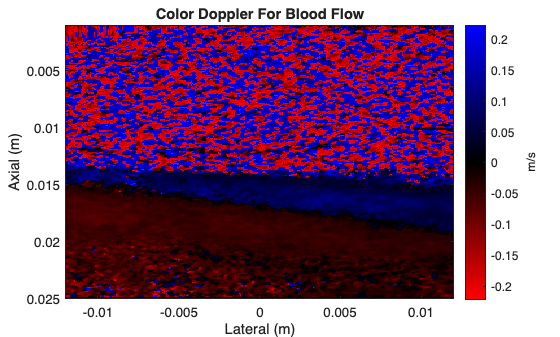

clf;
pruned_baseband = filtered(:, :, 3: 48);
prefix = -(c * prf) / (2 * 2 * pi * f0);
v_map = zeros(800, 300);
[Nd, N1, S] = size(pruned_baseband);
for i = 1:Nd - 5
    for j = 1:N1
        numerator = 0;
        denominator = 0;
        for m = i:i+5
            for n = 2:S
                numerator = numerator + (imag(pruned_baseband(m, j, n)) * real(pruned_baseband(m,j, n - 1)) - real(pruned_baseband(m,j, n)) * imag(pruned_baseband(m, j,n - 1)));
                denominator = denominator + (real(pruned_baseband(m,j, n)) * real(pruned_baseband(m,j, n - 1)) + imag(pruned_baseband(m,j, n)) * imag(pruned_baseband(m,j, n - 1)));
            end
        end
        v_map(i, j) = prefix * atan2(numerator, denominator);
    end
end

axis image;
imagesc(x, z, v_map);
clim([min(v_map(:)), max(v_map(:))]);
cb = colorbar;
cb.Label.String = 'm/s';
xlabel('Lateral (m)');
ylabel('Axial (m)');
title('Color Doppler For Blood Flow')
colormap(cmap_cf);

# Extension and Exploration

## Part A.

Located in "different_steering_angles.mlx".

## Part B.

clf;
imagesc(x, z, norm_envl_filtered);
cb = colorbar;
cb.Title.String = 'dB';
colormap gray;
title('B-mode Image of Filtered Baseband Data');
xlabel('Lateral (m)');
ylabel('Axial (m)');
clim([-60 0]);
ax = gca;
chart = ax.Children(1);
d2 = datatip(chart,0.005017,0.01812);
d1 = datatip(chart,-0.01184,0.01596);
hypotenuse = sqrt((d1.X - d2.X)^2 + (d1.Y - d2.Y)^2);
adjacent = d2.X - d1.X;
ang = acosd(adjacent / hypotenuse)

ang = 7.3113

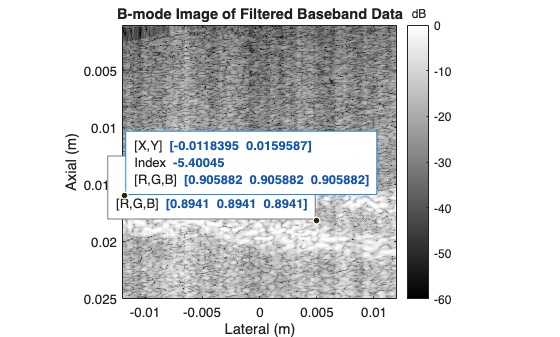

axis image;

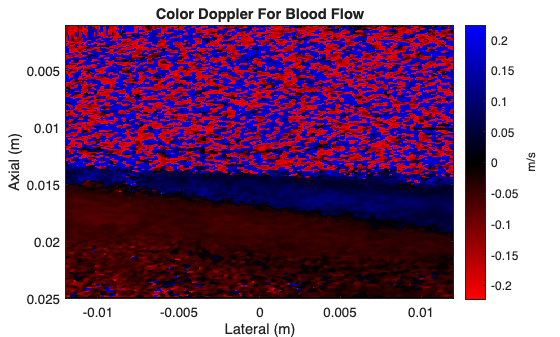

v_map = v_map ./ cosd(ang);
imagesc(x, z, v_map);
clim([min(v_map(:)), max(v_map(:))]);
cb = colorbar;
cb.Label.String = 'm/s';
xlabel('Lateral (m)');
ylabel('Axial (m)');
title('Color Doppler For Blood Flow')
colormap(cmap_cf);

## Part C.

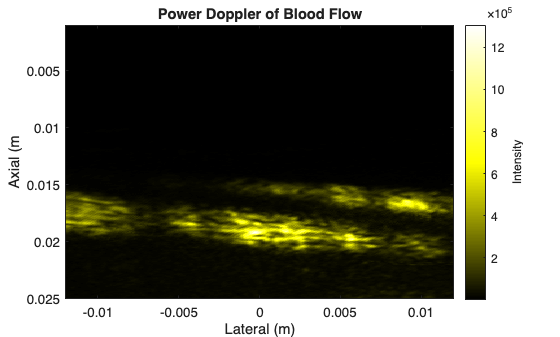

p = abs(filtered) .^ 2;
power_doppler = sum(p, 3);

imagesc(x, z, power_doppler);
cb = colorbar;
cb.Label.String = 'Intensity';
title('Power Doppler of Blood Flow');
xlabel('Lateral (m)');
ylabel('Axial (m');
colormap(cmap_pd);

## Part D. 

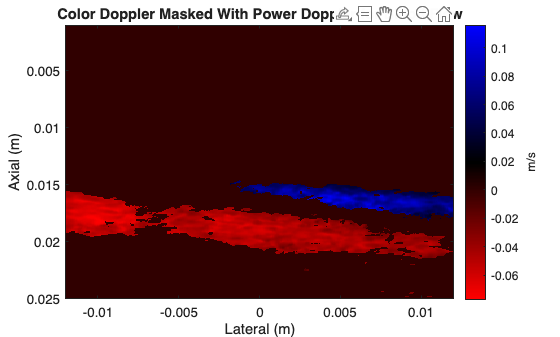

clf;
threshold = 80e3;
mask = power_doppler > threshold;
masked = v_map;
masked(~mask) = 0;
imagesc(x, z, masked);

cb = colorbar;
cb.Label.String = 'm/s';
xlabel('Lateral (m)');
ylabel('Axial (m)');
title('Color Doppler Masked With Power Doppler for Blood Flow')
clim([min(masked(:)), max(masked(:))]);
colormap(cmap_cf);